# EXERCISE #1 :Simulate the Simplest Bluetooth LE Network

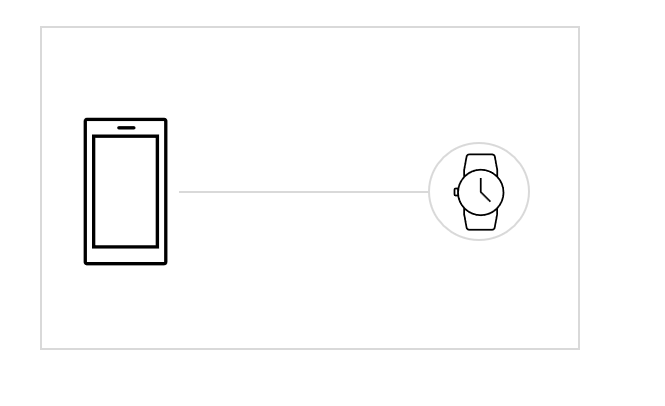

An example of two node Bluetooth LE network 

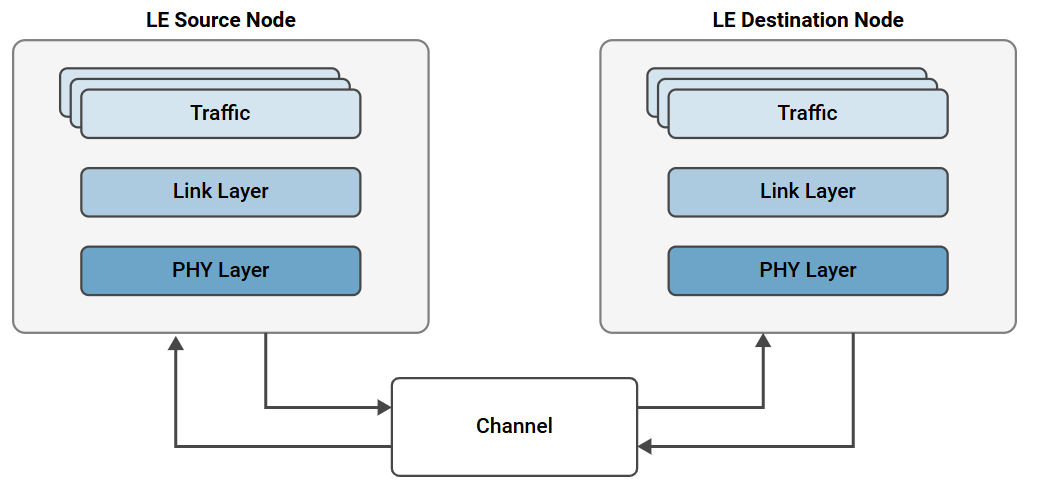

This exercise models all these blocks 

What you will model?   

- Model a Bluetooth LE network with one Central and one Peripheral

- Configure link-layer and physical-layer properties

- Add application traffic from Central to Peripheral

- Integrate a custom channel model

- Simulate the network and collect node statistics 

- Visualize Bluetooth Low Energy packets and IQ samples

What you will do? 

- Complete 9 tasks to implement the model; each requires no more than one line of MATLAB code

- Run each task independently is in a separate section, but should be executed in sequence

- Additional code for visualization, logging, and post-simulation analysis is already provided, you only need to execute it

- Perform cleanup by closing previously opened windows and figures. 

clear all;
all_figs = findall(0, 'type', 'figure');close(all_figs); 

- Initialize the random number generator for reproducibility

- Set the simulation time

- Initialize the network simulator

- Launch the wireless network viewer to visualize the network during simulation

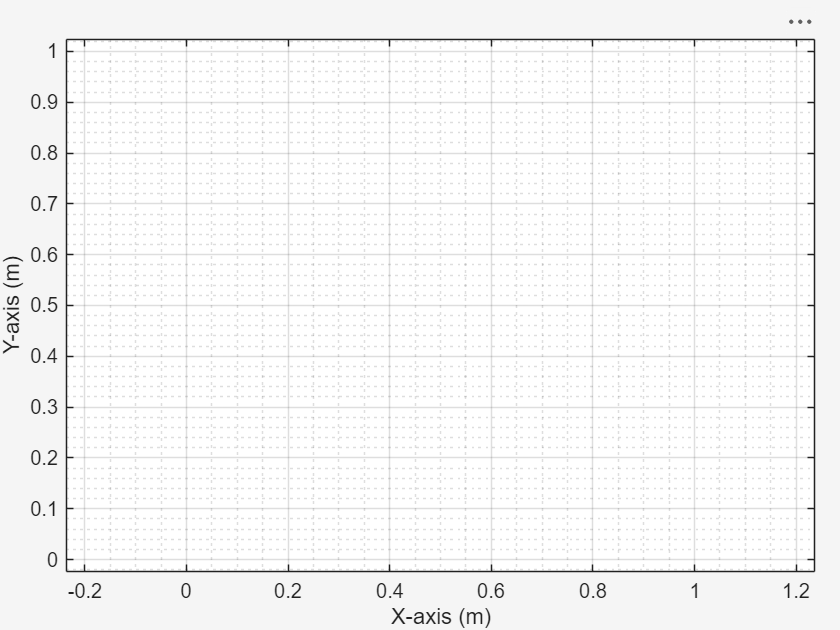

rng(1,"twister");
simulationTime = 0.5;
networkSimulator = wirelessNetworkSimulator.init;
viewerObj = wirelessNetworkViewer();

# Task 1/9: Create a Bluetooth LE Central Node

**Description of the task**

- Create a Bluetooth Low Energy (LE) central node

- A central node 

- Manages connections, 

- Discovers nearby peripherals

- Initiates communication

- Coordinates data exchange

- Configure parameters such as role, name, position, and transmit power

- Add the node to the Wireless Network Viewer

- Refer to documentation for more details on creating a Bluetooth LE node (Type *doc bluetoothLENode* in command window)

**Instructions to complete the task**

Use bluetoothLENode() function to create a central node 

Store the node in a variable named "centralNode"

Hint: Type "doc bluetoothLENode" in the MATLAB Command Window for details 

Note : use the following values as arguments to bluetoothLENode()

- "central"

- Name = "Central"

- Position=[0 0 0]

% Enter Code Here
% centralNode =  

####  Visualize the Central node in the Network Viewer 

Add node to he network viewer for visualization 

addNodes(viewerObj,centralNode,Type="Source",Name=centralNode.Name);

# Task 2/9: Create a Bluetooth LE Peripheral Node

**Instructions to complete the task**

Use bluetoothLENode() function to create a peripheral node 

Store the node in a variable named "peripheralNode"

Hint: Type "doc bluetoothLENode" in the MATLAB Command Window for details 

Note : use the following values as arguments to bluetoothLENode()

- "peripheral"

- Name = "Peripheral""

- Position=[0 0 0]

% Enter Code Here
% peripheralNode = 

#### Visualize the Peripheral node in the Network Viewer 

Add node to he network viewer for visualization 

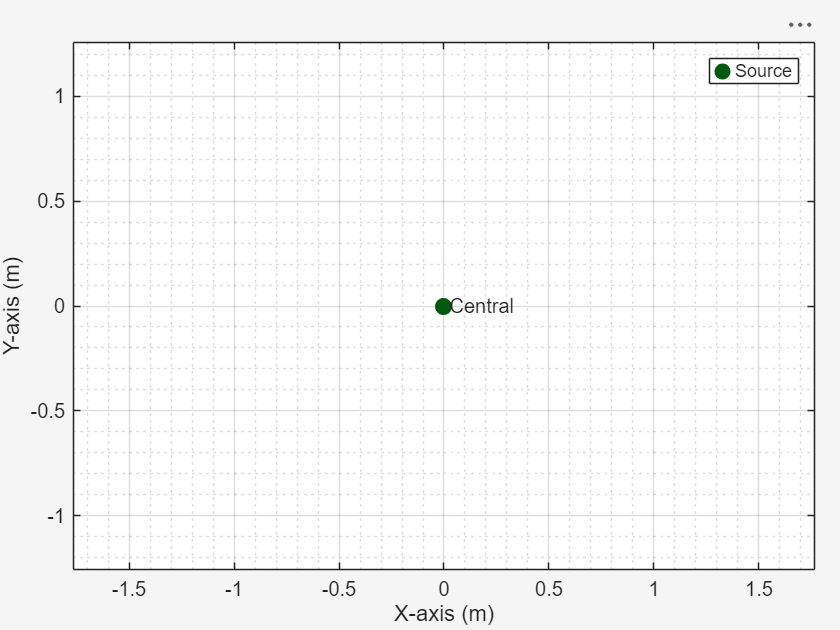

addNodes(viewerObj,peripheralNode,Type="Sink",Name=peripheralNode.Name);

#### Configure the Connection between Bluetooth LE Nodes   

**Description of the task**

Bluetooth LE supports multiple **PHY configurations** : LE 1M and LE 2M for standard and high-speed communication, and LE Coded PHY for long-range links with forward error correction.

The **connection event**, defines how often devices communicate. Bluetooth LE performs frequency hopping at the start of each connection event. Connection interval is elapse time between two connection events 

The **Access Address** identifies packets belonging to a specific Bluetooth LE connection. The Bluetooth SIG defines rules for a valid Access Address

**Instructions to complete the task**

Use bluetoothLEConnectionConfig() function to configure the connection 

Write configuration in a variable named "cfgConnection"

Hint: Type "doc bluetoothLEConnectionConfig" in the MATLAB Command Window, and see the "Syntax" section.

Note : use the following values to start with

- PHYMode = "LE1M" 

- ConnectionInterval=0.050

- AccessAddress="5DA44270"

% Enter Code Here
% cfgConnection = 

# Task 3/9: Connect the central and peripheral Nodes

**Description of the Task**

In this task, we connect the Central and Peripheral nodes using a function call. In real-world scenarios, Bluetooth devices automatically scan and connect.

From R2026a onwards, you can configure and simulate the [Bluetooth LE connection establishment procedure](https://www.mathworks.com/help/releases/R2026a/bluetooth/ref/bluetoothlegapconfig.html) between a Central node and multiple Peripheral nodes using GAP (Generic Access Profile) configuration.

**Instructions to complete the task**

Use configureConnection() function to configure connection 

Hint: Type "doc configureConnection" in the MATLAB Command Window, and see the "Syntax" section. 

Note : use the following values as arguments 

- cfgConnection

- centralNode

- peripheralNode

% Enter Code Here


# Task 4/9: Create a custom channel and add it to the simulation   

**Description of the task**

Bluetooth uses several techniques that mitigate multipath fading: 

- Frequency Hopping Spread Spectrum (FHSS)

- Short Packets

- Error Correction & Retransmissions

Forward Error Correction (FEC) and Automatic Repeat Request (ARQ) reduce the effect of fading-induced errors.

Bluetooth SIG – Signal Propagation Environments, specified as "Home", "Industrial", "Office", or "Outdoor".

More Signal Propagation Environments for Bluetooth Research 

- Retail / Shopping Mall

- Hospital / Healthcare

- Warehouse / Storage Facility

- Stadium / Arena / Large Public Venue

- Transportation Environments

You can define you custom channel model and plug into the simulation   

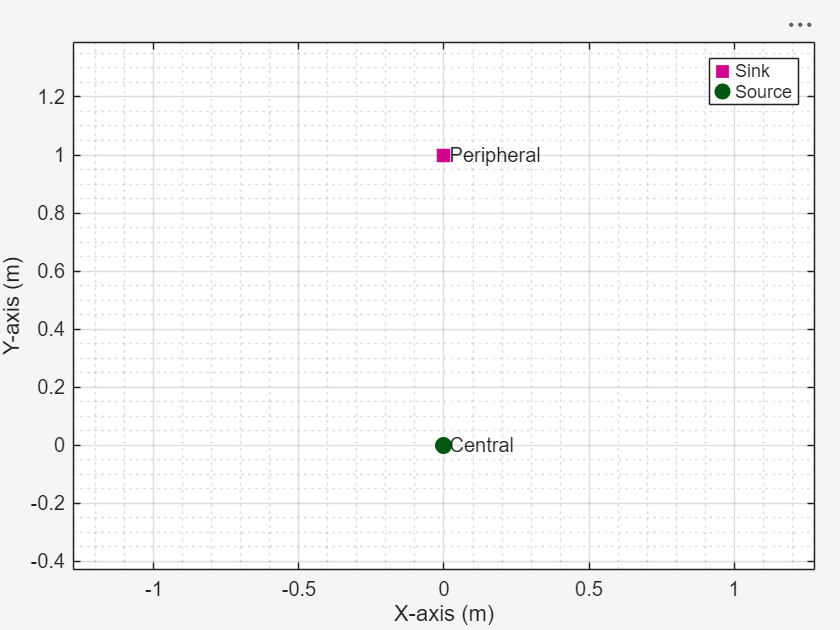

% Enter Code Here
function rxData = addImpairment(rxInfo,txData)
% Create a path loss configuration for the operating environment
% (e.g., "Home", "Industrial", "Office", or "Outdoor")
pathlossCfg = bluetoothPathLossConfig(Environment="Industrial", PathLossExponent=2.2);
rxData = txData;

% Calculate the distance between transmitter and receiver in meters
distance = norm(rxData.TransmitterPosition - rxInfo.Position);
% Calculate the path loss based on distance and path loss configuration 
pathloss = bluetoothPathLoss(distance,pathlossCfg);
% Path loss is in dBm
rxData.Power = rxData.Power-pathloss;                          
% Covert to linear scale 
scale = 10.^(-pathloss/20);
[numSamples,~] = size(rxData.Data);
% Apply path loss and update output signal
rxData.Data(1:numSamples,:) = rxData.Data(1:numSamples,:)*scale;
end

**Instructions to complete the task**

Use addChannelModel() to integrate the channel model into simulation  

Hint: Type "doc addChannelModel" in the MATLAB Command Window, and see the "Syntax" section. 

Note : use the following values as arguments 

- networkSimulator

- @addImpairment

% Enter Code Here


# Task 5/9: Create a traffic model 

**Description of the task**

Application Traffic Pattern Modeling

- On-Off Traffic (Periodic, Bursty, or Random) – Represents intermittent data transmission patterns with varying activity periods.

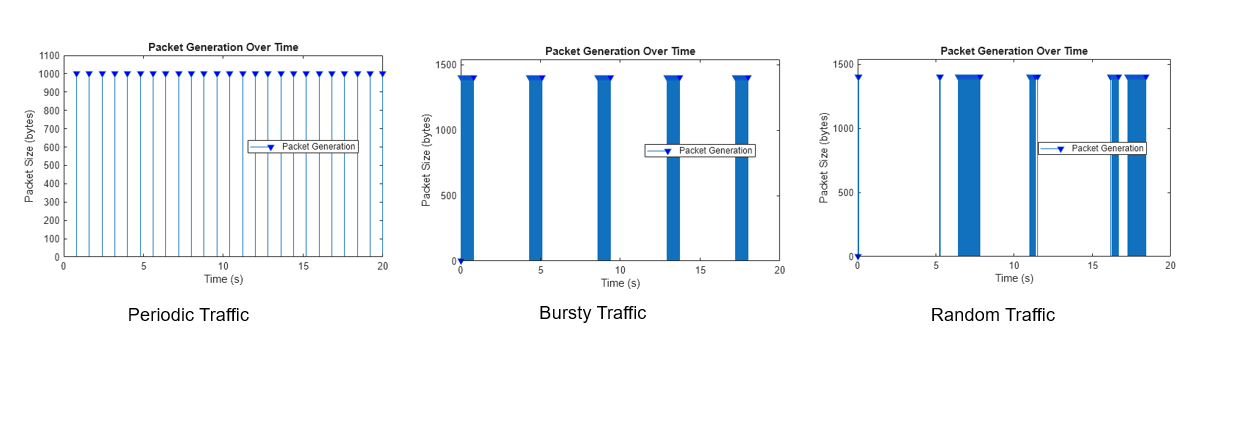

Other supported application traffic models 

- FTP (File Transfer Protocol) – Models file-based data transfer sessions.

- Video Streaming – Simulates continuous media flow with variable bit rates.

- Voice over IP (VoIP) – Models real-time voice communication traffic.

**Instructions to complete the task**

Use networkTrafficOnOff() function to configure application layer traffic. 

Write configuration in a variable named "traffic". 

Type "doc networkTrafficOnOff" in the MATLAB Command Window, and see the "Syntax" section.

Note : use the following values as arguments, data rate is in kbps and packet size is in Bytes, time is in seconds  

- DataRate= 30

- PacketSize= 251

- OnTime= simulationTime

- OffTime=0

% <enter code below>
% traffic= 

#### Visualize the configured traffic pattern 

plotTrafficPattern(simulationTime,traffic);

# Task 6/9: Add traffic from Central to Peripheral

**Instructions to complete the task**

Use addTrafficSource() function to add application traffic to the nodes  

Type "doc addTrafficSource" in the MATLAB Command Window, and see the "Syntax" section.

Note : use the following values as arguments 

- centralNode

- traffic

- "DestinationNode",peripheralNode

% <enter code below>


# Task 7/9: Add traffic from Peripheral to Central

**Instructions to complete the task**

Use addTrafficSource() function to add application traffic to the nodes  

Type "doc addTrafficSource" in the MATLAB Command Window, and see the "Syntax" section.

Note : use the following values as arguments 

- peripheralNode

- traffic

- "DestinationNode",centralNode

% <enter code below>


# Task 8/9: Add the network nodes to the wireless network simulator

**Instructions to complete the task**

Use addNodes() function to add Bluetooth LE nodes to the network simulator   

Type "doc addNodes" in the MATLAB Command Window, and see the "Syntax" section.

Note : use the following values as arguments 

- networkSimulator

- nodes

nodes = [centralNode peripheralNode];
% <enter code below>


####  Enable the Bluetooth LE Network Event Tracer 

Log, read, and filter events from Bluetooth nodes, such as "TransmissionStarted", "ReceptionEnded", "AppPacketGenerated", and "AppPacketReceived".

eventTracer = wirelessNetworkEventTracer;
addNodes(eventTracer,[centralNode peripheralNode]);

#### Enable visualization of packet communication and state transitions 

The visualization shows the packet communication and state transitions of Bluetooth LE nodes over time

viewerObj = wirelessTrafficViewer;
addNodes(viewerObj,nodes);

####  Enable packet capture for Wireshark visualization 

Capture packets for all nodes in the network and visualize them in Wireshark, similar to real-world Bluetooth network behavior.

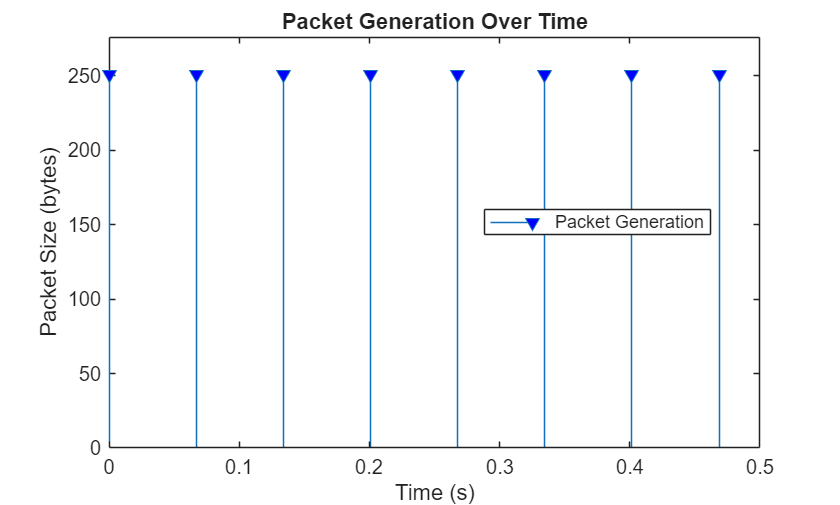

packetCaptureObj = blePCAPWriter(Node=nodes,FileExtension="pcap");

#### Enable capture of IQ samples 

Capture IQ samples for all nodes and visualize them in the time and frequency domains

iqSampleObj = wirelessIQLogger(nodes);

# Task 9/9: Run the simulation

Runs the discrete-event simulator in MATLAB to execute the network model.

% <enter code below>


#### Visualize statistics 

View packet statistics and the time spent by nodes in different states such as Transmit, Receive, Idle, and Sleep.

centralStats = statistics(centralNode);
centralStats.App.AggregatePacketLatency
centralStats.LL.SleepTime
centralStats.PHY.TransmittedPackets
peripheralStats = statistics(peripheralNode);

####  Measure link layer, and App layer KPIs 

Measure throughput, latency, and packet loss ratio at the link layer and application layer.

throughput = kpi(centralNode,peripheralNode,"throughput",Layer="LL")
latency = kpi(centralNode,peripheralNode,"latency",Layer="App")
packetLossRatio = kpi(centralNode,peripheralNode,"PLR",Layer="App")

#### IQ sample visualization 

Visualize IQ samples in the time and frequency domains.

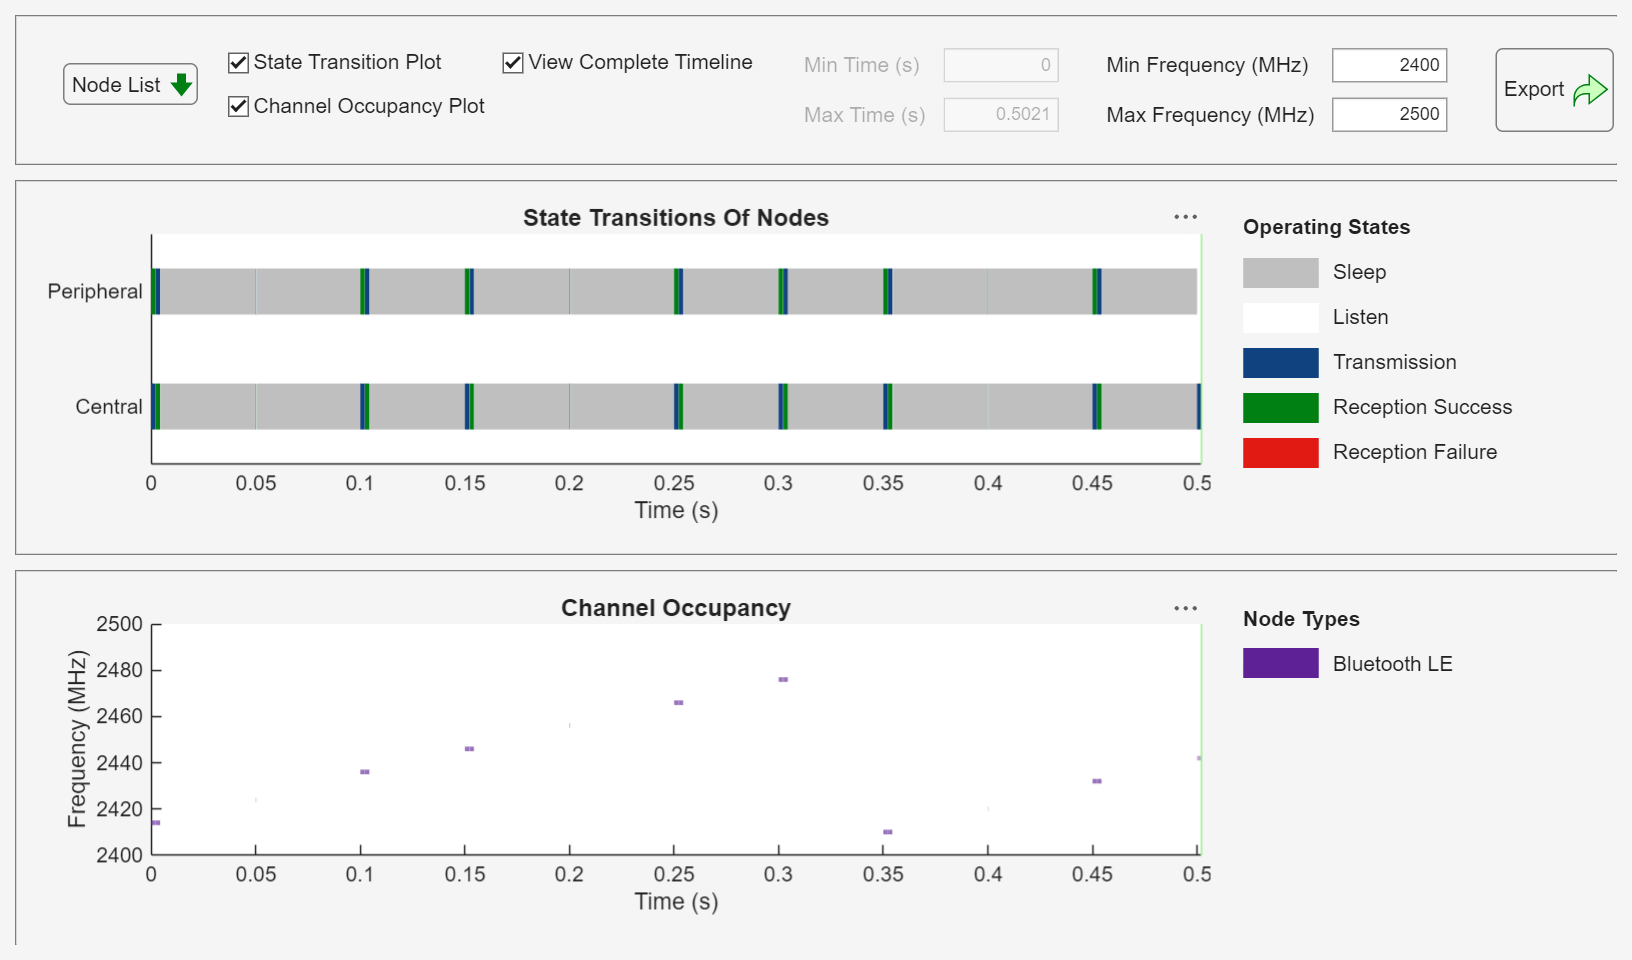

ans = 0.2247

ans = 0.4673

ans = 11

throughput = 32.1280

latency = 0.0299

packetLossRatio = 0.1250

fileName = iqSampleObj(1).FileName;
iqData = load(fileName);
signalAnalyzer(iqData.Waveform,SampleRate=iqData.Fs);
delete(packetCaptureObj);

Copyright 2021-2023 The MathWorks, Inc.